# Assignment 1 -- Linear Regression

## Import data

clear
T = readtable('slump_test.csv','PreserveVariableNames',true);
row_offset = 1;
col_offset = 1;
data = csvread('slump_test.csv', row_offset, col_offset);
[n, d] = size(data);

## Train-test split

[train_sample, test_sample] = split_sample(data, 0.9, 1);
[train_size, feature_size] = size(train_sample);
[test_size, ~] = size(test_sample);

## Simple linear regression

Regress compressive strength on water, with an intercept:

regressor_ind = 4;
explained_var_ind = 10;

X_train = [ones(train_size, 1), train_sample(:, regressor_ind)];
Y_train = train_sample(:, explained_var_ind);
X_test = [ones(test_size, 1), test_sample(:, regressor_ind)];
Y_test = test_sample(:, explained_var_ind);

Apply the closed-form normal equation:

beta_OLS_explicit_water = OLS_normalequation(X_train, Y_train);

Compare with the result from Matlab internal regression function:

[beta_OLS_water, beta_OLS_confint_water] = regress(Y_train, X_train);

### Compute training error

Construct the output of the trained (estimated) model or the in-sample values of the explained variable.

Y_hat_train = X_train * beta_OLS_water;

Loss L1:

loss_l1_water_train = loss_l1(Y_hat_train, Y_train);
disp('Results for using water as regressor: ')

Results for using water as regressor: 


disp(['The training error measured by l1 loss is ', num2str(loss_l1_water_train)]);

The training error measured by l1 loss is 5.8459


Loss L2:

loss_l2_water_train = loss_l2(Y_hat_train, Y_train);
disp(['The training error measured by l2 loss is ', num2str(loss_l2_water_train)]);

The training error measured by l2 loss is 53.6749


Huber loss:

% Set Delta in the Huber loss function to 3 times the standard deviation of
% the training set, as a threshold for detecting outliers
disp('We set Delta in the Huber loss function to 3 times the standard deviation of the training set, as a threshold for detecting outliers')

We set Delta in the Huber loss function to 3 times the standard deviation of the training set, as a threshold for detecting outliers


delta = 3 * std(Y_train);
loss_huber_water_train = loss_huber(Y_hat_train, Y_train, delta);
disp(['The training error measured by Huber loss is ', num2str(loss_huber_water_train)]);

The training error measured by Huber loss is 26.8374


### Compute test error

Y_hat_test = X_test * beta_OLS_water;

Loss L1:

loss_l1_water_test = loss_l1(Y_hat_test, Y_test);
disp(['The test error measured by l1 loss is ', num2str(loss_l1_water_test)]);

The test error measured by l1 loss is 7.8491


Loss L2:

loss_l2_water_test = loss_l2(Y_hat_test, Y_test);
disp(['The test error measured by l2 loss is ', num2str(loss_l2_water_test)]);

The test error measured by l2 loss is 87.5048


Huber loss:

loss_huber_water_test = loss_huber(Y_hat_test, Y_test, delta);
disp(['The test error measured by Huber loss is ', num2str(loss_huber_water_train)]);

The test error measured by Huber loss is 26.8374


### Plot

Plot the scatter plot and the fitted function for the training set:

disp('Plot for training data: ')

Plot for training data: 


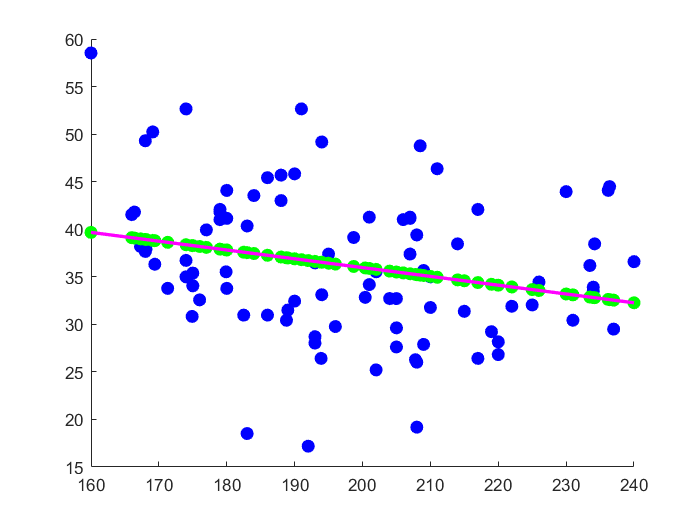

figure(1)
% the ground-truth data points
scatter(X_train(:, 2), Y_train, 40, 'MarkerFaceColor', [0 0 1], ...
              'MarkerEdgeColor', [0 0 1], ...
              'LineWidth', 1.5);
hold on;

% the predicted points 
scatter(X_train(:, 2), Y_hat_train, 40, 'MarkerFaceColor', [0 1 0], ...
              'MarkerEdgeColor', [0 1 0], ...
              'LineWidth', 1.5);
hold on;

% the regression line
plot(X_train(:, 2), Y_hat_train, 'magenta', 'LineWidth',2); 
hold off;

Plot the scatter plot and the fitted function for the test set:

disp('Plot for test data: ')

Plot for test data: 


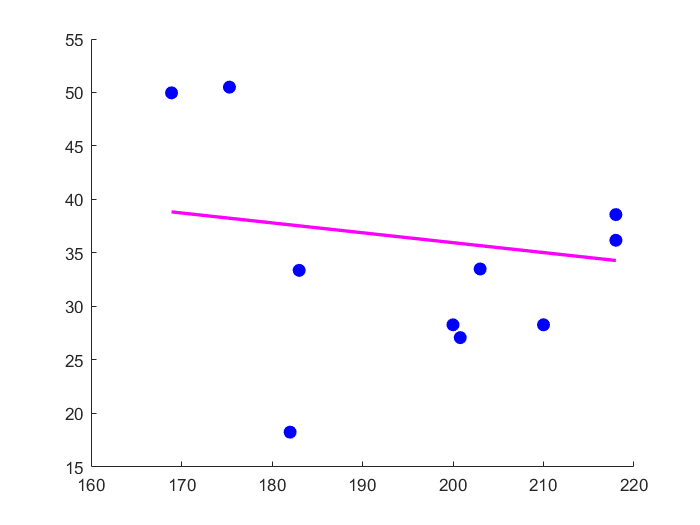

figure(2)
scatter(X_test(:, 2), Y_test, 40, 'MarkerFaceColor', [0 0 1], ...
              'MarkerEdgeColor', [0 0 1], ...
              'LineWidth', 1.5);
hold on;
plot(X_test(:, 2), Y_hat_test, 'magenta', 'LineWidth',2); 
hold off;

### LOOCV

folds_LOOCV = kfold_split(train_sample, train_size);
%Stack estimates from every loop into one matrix, not in use at present
%beta_OLS_explicit_water_LOOCV = ones(2, train_size);
loss_l1_sum_LOOCV = 0;
loss_l2_sum_LOOCV = 0;
loss_huber_sum_LOOCV = 0;
for i = 1 : train_size
    rng(1);
    kminusonefolds = cell2mat(folds_LOOCV(setdiff(randperm(train_size), [i]), :));
    onefold = cell2mat(folds_LOOCV(i, :));
    X_kminusonefolds = [ones(train_size - 1, 1), kminusonefolds(:, regressor_ind)];
    Y_kminusonefolds = kminusonefolds(:, explained_var_ind);
    X_onefold = [ones(1, 1), onefold(:, regressor_ind)];
    Y_onefold = onefold(:, explained_var_ind);
    %beta_OLS_explicit_water_LOOCV(:, i) = OLS_normalequation(X_kminusonefolds, Y_kminusonefolds);
    Y_hat_onefold = X_onefold * OLS_normalequation(X_kminusonefolds, Y_kminusonefolds);
    loss_l1_sum_LOOCV = loss_l1_sum_LOOCV + loss_l1(Y_hat_onefold, Y_onefold);
    loss_l2_sum_LOOCV = loss_l2_sum_LOOCV + loss_l2(Y_hat_onefold, Y_onefold);
    loss_huber_sum_LOOCV = loss_huber_sum_LOOCV + loss_huber(Y_hat_onefold, Y_onefold, delta);
end
loss_l1_water_LOOCV = loss_l1_sum_LOOCV / train_size;
loss_l2_water_LOOCV = loss_l2_sum_LOOCV / train_size;
loss_huber_water_LOOCV = loss_huber_sum_LOOCV / train_size;
disp(['The LOOCV error measured by l1 loss is ', num2str(loss_l1_water_LOOCV)]);

The LOOCV error measured by l1 loss is 5.9706


disp(['The LOOCV error measured by l2 loss is ', num2str(loss_l2_water_LOOCV)]);

The LOOCV error measured by l2 loss is 56.0316


disp(['The LOOCV error measured by Huber loss is ', num2str(loss_huber_water_LOOCV)]);

The LOOCV error measured by Huber loss is 28.0158


### K-fold validation

k = 10;
folds_kfold = kfold_split(train_sample, k);
%Stack estimates from every loop into one matrix, not in use at present
%beta_OLS_explicit_water_kfold = ones(2, k);
loss_l1_sum_kfold = 0;
loss_l2_sum_kfold = 0;
loss_huber_sum_kfold = 0;
for i = 1 : k
    rng(1);
    kminusonefolds = cell2mat(folds_kfold(setdiff(randperm(k), [i]), :));
    [kminusonefolds_size, ~] = size(kminusonefolds); %Size varies
    onefold = cell2mat(folds_kfold(i, :));
    X_kminusonefolds = [ones(kminusonefolds_size, 1), kminusonefolds(:, regressor_ind)];
    Y_kminusonefolds = kminusonefolds(:, explained_var_ind);
    X_onefold = [ones(train_size - kminusonefolds_size, 1), onefold(:, regressor_ind)];
    Y_onefold = onefold(:, explained_var_ind);
    %beta_OLS_explicit_water_kfold(:, i) = OLS_normalequation(X_kminusonefolds, Y_kminusonefolds);
    Y_hat_onefold = X_onefold * OLS_normalequation(X_kminusonefolds, Y_kminusonefolds);
    loss_l1_sum_kfold = loss_l1_sum_kfold + loss_l1(Y_hat_onefold, Y_onefold);
    loss_l2_sum_kfold = loss_l2_sum_kfold + loss_l2(Y_hat_onefold, Y_onefold);
    loss_huber_sum_kfold = loss_huber_sum_kfold + loss_huber(Y_hat_onefold, Y_onefold, delta);
end
loss_l1_water_kfold = loss_l1_sum_kfold / k;
loss_l2_water_kfold = loss_l2_sum_kfold / k;
loss_huber_water_kfold = loss_huber_sum_kfold / k;
disp(['The kfold error measured by l1 loss is ', num2str(loss_l1_water_kfold)]);

The kfold error measured by l1 loss is 6.2016


disp(['The kfold error measured by l2 loss is ', num2str(loss_l2_water_kfold)]);

The kfold error measured by l2 loss is 60.8224


disp(['The kfold error measured by Huber loss is ', num2str(loss_huber_water_kfold)]);

The kfold error measured by Huber loss is 30.4112


## Multiple regression

regressor_ind = [4, 6];
explained_var_ind = 10;

### Normalization

Normalize the training sample: 

[X_norm, mu_x, sigma_x] = featureNormalize(train_sample(:, regressor_ind));

X_train = [ones(train_size, 1), X_norm];
Y_train = train_sample(:, explained_var_ind);

Apply the same transformation on the test sample:

test_sample_temp = test_sample(:, regressor_ind) - mu_x;
test_sample_temp = test_sample_temp ./ sigma_x;
X_test = [ones(test_size, 1), test_sample_temp];
Y_test = test_sample(:, explained_var_ind);

Apply the closed-form normal equation:

beta_OLS_explicit_water_coarseaggr = OLS_normalequation(X_train, Y_train);

Compare with the result from Matlab internal regression function:

[beta_OLS_water_coarseaggr, beta_OLS_confint_water_coarseaggr] = regress(Y_train, X_train);

### Compute training error

Construct the output of the trained (estimated) model or the in-sample values of the explained variable.

Y_hat_train = X_train * beta_OLS_water_coarseaggr;

Loss L1:

loss_l1_water_coarseaggr_train = loss_l1(Y_hat_train, Y_train);
disp('Results for using water and coarse aggregate as regressors: ')

Results for using water and coarse aggregate as regressors: 


disp(['The training error measured by l1 loss is ', num2str(loss_l1_water_coarseaggr_train)]);

The training error measured by l1 loss is 5.1398


Loss L2:

loss_l2_water_coarseaggr_train = loss_l2(Y_hat_train, Y_train);
disp(['The training error measured by l2 loss is ', num2str(loss_l1_water_coarseaggr_train)]);

The training error measured by l2 loss is 5.1398


Huber loss:

loss_huber_water_coarseaggr_train = loss_huber(Y_hat_train, Y_train, delta);
disp(['The training error measured by Huber loss is ', num2str(loss_huber_water_coarseaggr_train)]);

The training error measured by Huber loss is 22.711


### Compute test error

Y_hat_test = X_test * beta_OLS_water_coarseaggr;

Loss L1:

loss_l1_water_coarseaggr_test = loss_l1(Y_hat_test, Y_test);
disp(['The test error measured by l1 loss is ', num2str(loss_l1_water_coarseaggr_test)]);

The test error measured by l1 loss is 6.916


Loss L2:

loss_l2_water_coarseaggr_test = loss_l2(Y_hat_test, Y_test);
disp(['The test error measured by l1 loss is ', num2str(loss_l2_water_coarseaggr_test)]);

The test error measured by l1 loss is 67.4644


Huber loss:

loss_huber_water_coarseaggr_test = loss_huber(Y_hat_test, Y_test, delta);
disp(['The test error measured by l1 loss is ', num2str(loss_huber_water_coarseaggr_train)]);

The test error measured by l1 loss is 22.711


### Plot

Plot the scatter plot and the fitted function for the training set:

disp('Plot for training data: ')

Plot for training data: 


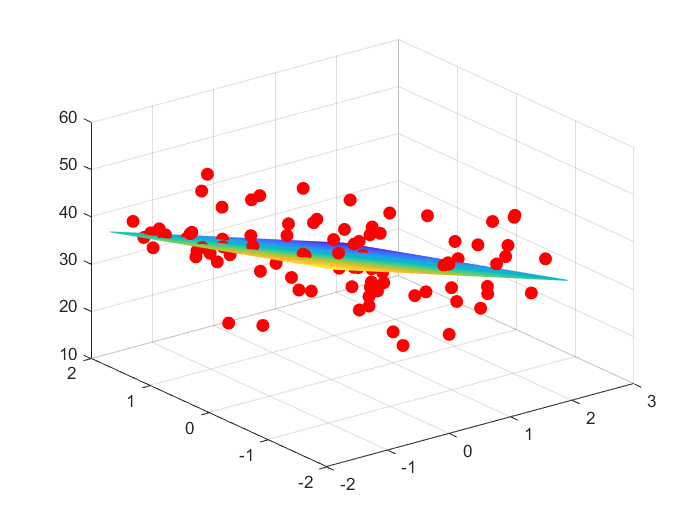

figure(3)
X1 = min(X_train(:, 2)):0.1:max(X_train(:, 2));
X2 = min(X_train(:, 3)):0.1:max(X_train(:, 3));
[X1, X2] = meshgrid(X1, X2);
Z = beta_OLS_water_coarseaggr(1) + X1 * beta_OLS_water_coarseaggr(2) + X2 * beta_OLS_water_coarseaggr(3);
mesh(X1, X2, Z, 'EdgeColor','interp');
hold on;
scatter3(X_train(:, 2), X_train(:, 3), Y_train, 40, 'MarkerFaceColor', [1 0 0],...
              'MarkerEdgeColor', [1 0 0], ...
              'LineWidth', 1.5);
hold off;

Plot the scatter plot and the fitted function for the test set:

disp('Plot for test data: ')

Plot for test data: 


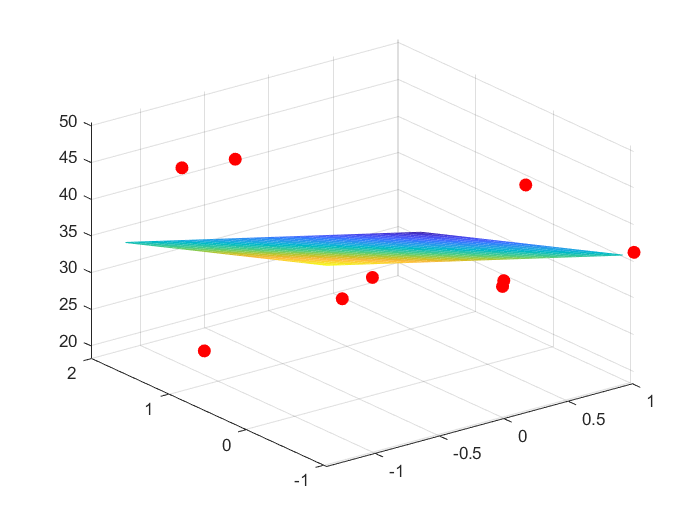

figure(4)
X1 = min(X_test(:, 2)):0.1:max(X_test(:, 2));
X2 = min(X_test(:, 3)):0.1:max(X_test(:, 3));
[X1, X2] = meshgrid(X1, X2);
Z = beta_OLS_water_coarseaggr(1) + X1 * beta_OLS_water_coarseaggr(2) + X2 * beta_OLS_water_coarseaggr(3);
mesh(X1, X2, Z, 'EdgeColor','interp');
hold on;
scatter3(X_test(:, 2), X_test(:, 3), Y_test, 40, 'MarkerFaceColor', [1 0 0],...
              'MarkerEdgeColor', [1 0 0], ...
              'LineWidth', 1.5);
hold off;

### LOOCV

folds_LOOCV = kfold_split(train_sample, train_size);
loss_l1_sum_LOOCV = 0;
loss_l2_sum_LOOCV = 0;
loss_huber_sum_LOOCV = 0;

for i = 1 : train_size
    rng(1);
    kminusonefolds = cell2mat(folds_LOOCV(setdiff(randperm(train_size), [i]), :));
    onefold = cell2mat(folds_LOOCV(i, :));
    
    [X_norm, mu_x, sigma_x] = featureNormalize(kminusonefolds(:, regressor_ind));

    X_kminusonefolds = [ones(train_size - 1, 1), X_norm];
    Y_kminusonefolds = kminusonefolds(:, explained_var_ind);

    onefold_temp = onefold(:, regressor_ind) - mu_x;
    onefold_temp = onefold_temp ./ sigma_x;
    X_onefold = [ones(1, 1), onefold_temp];
    Y_onefold = onefold(:, explained_var_ind);

    Y_hat_onefold = X_onefold * OLS_normalequation(X_kminusonefolds, Y_kminusonefolds);
    loss_l1_sum_LOOCV = loss_l1_sum_LOOCV + loss_l1(Y_hat_onefold, Y_onefold);
    loss_l2_sum_LOOCV = loss_l2_sum_LOOCV + loss_l2(Y_hat_onefold, Y_onefold);
    loss_huber_sum_LOOCV = loss_huber_sum_LOOCV + loss_huber(Y_hat_onefold, Y_onefold, delta);
end
loss_l1_water_coarseaggr_LOOCV = loss_l1_sum_LOOCV / train_size;
loss_l2_water_coarseaggr_LOOCV = loss_l2_sum_LOOCV / train_size;
loss_huber_water_coarseaggr_LOOCV = loss_huber_sum_LOOCV / train_size;
disp(['The LOOCV error measured by l1 loss is ', num2str(loss_l1_water_coarseaggr_LOOCV)]);

The LOOCV error measured by l1 loss is 5.3011


disp(['The LOOCV error measured by l2 loss is ', num2str(loss_l2_water_coarseaggr_LOOCV)]);

The LOOCV error measured by l2 loss is 48.3103


disp(['The LOOCV error measured by Huber loss is ', num2str(loss_huber_water_coarseaggr_LOOCV)]);

The LOOCV error measured by Huber loss is 24.1552


### K-fold validation

k = 10;
folds_kfold = kfold_split(train_sample, k);
loss_l1_sum_kfold = 0;
loss_l2_sum_kfold = 0;
loss_huber_sum_kfold = 0;
for i = 1 : k
    rng(1);
    kminusonefolds = cell2mat(folds_kfold(setdiff(randperm(k), [i]), :));
    [kminusonefolds_size, ~] = size(kminusonefolds); %Size varies
    onefold = cell2mat(folds_kfold(i, :));
    
    [X_norm, mu_x, sigma_x] = featureNormalize(kminusonefolds(:, regressor_ind));
    
    X_kminusonefolds = [ones(kminusonefolds_size, 1), X_norm];
    Y_kminusonefolds = kminusonefolds(:, explained_var_ind);
    
    onefold_temp = onefold(:, regressor_ind) - mu_x;
    onefold_temp = onefold_temp ./ sigma_x;
    X_onefold = [ones(train_size - kminusonefolds_size, 1), onefold_temp];
    Y_onefold = onefold(:, explained_var_ind);
    
    Y_hat_onefold = X_onefold * OLS_normalequation(X_kminusonefolds, Y_kminusonefolds);
    loss_l1_sum_kfold = loss_l1_sum_kfold + loss_l1(Y_hat_onefold, Y_onefold);
    loss_l2_sum_kfold = loss_l2_sum_kfold + loss_l2(Y_hat_onefold, Y_onefold);
    loss_huber_sum_kfold = loss_huber_sum_kfold + loss_huber(Y_hat_onefold, Y_onefold, delta);
end
loss_l1_water_coarseaggr_kfold = loss_l1_sum_kfold / k;
loss_l2_water_coarseaggr_kfold = loss_l2_sum_kfold / k;
loss_huber_water_coarseaggr_kfold = loss_huber_sum_kfold / k;
disp(['The kfold error measured by l1 loss is ', num2str(loss_l1_water_coarseaggr_kfold)]);

The kfold error measured by l1 loss is 5.4657


disp(['The kfold error measured by l2 loss is ', num2str(loss_l2_water_coarseaggr_kfold)]);

The kfold error measured by l2 loss is 51.1841


disp(['The kfold error measured by Huber loss is ', num2str(loss_huber_water_coarseaggr_kfold)]);

The kfold error measured by Huber loss is 25.5921


Actually, normalization doesn't seem to affect the results of OLS...

## Predictor filtering

SLUMP and FLOW are output variables, so we discard them from regressors

X_train = train_sample(:, setdiff(1: feature_size - 3, explained_var_ind));
Y_train = train_sample(:, explained_var_ind);

R = predictorFiltering(X_train, Y_train);
disp(['The Pearson correlation coefficient for all predictors are ', num2str(R)])

The Pearson correlation coefficient for all predictors are 0.44419      -0.351     0.43125    -0.24992  -0.0073765    -0.14734    -0.14446


## Stepwise forward subset selection (using the whole training set)

k = train_size;
folds_kfold = kfold_split(train_sample, k);
regressor_ind = [];
loss_min_chosen = [];
while ~isempty(setdiff(1 : feature_size - 3, regressor_ind))
loss_l1_kfold = [];
loss_l2_kfold = [];
regressor_ind_add_all = setdiff(1 : feature_size - 3, regressor_ind);
for regressor_ind_add = regressor_ind_add_all
loss_l1_sum_kfold = 0;
loss_l2_sum_kfold = 0;
regressor_ind(end + 1) = regressor_ind_add;
for i = 1 : k
    rng(1);
    kminusonefolds = cell2mat(folds_kfold(setdiff(randperm(k), [i]), :));
    [kminusonefolds_size, ~] = size(kminusonefolds); %Size varies
    onefold = cell2mat(folds_kfold(i, :));
    
    [X_norm, mu_x, sigma_x] = featureNormalize(kminusonefolds(:, regressor_ind));
    
    X_kminusonefolds = [ones(kminusonefolds_size, 1), X_norm];
    Y_kminusonefolds = kminusonefolds(:, explained_var_ind);
    
    onefold_temp = onefold(:, regressor_ind) - mu_x;
    onefold_temp = onefold_temp ./ sigma_x;
    X_onefold = [ones(train_size - kminusonefolds_size, 1), onefold_temp];
    Y_onefold = onefold(:, explained_var_ind);
    
    Y_hat_onefold = X_onefold * OLS_normalequation(X_kminusonefolds, Y_kminusonefolds);
    loss_l1_sum_kfold = loss_l1_sum_kfold + loss_l1(Y_hat_onefold, Y_onefold);
    loss_l2_sum_kfold = loss_l2_sum_kfold + loss_l2(Y_hat_onefold, Y_onefold);
end
loss_l1_kfold(end + 1) = loss_l1_sum_kfold / k;
loss_l2_kfold(end + 1) = loss_l2_sum_kfold / k;
regressor_ind = regressor_ind(1 : (end - 1));
end
% Here we only use loss_l2
[loss_min, loss_min_ind] = min(loss_l2_kfold);
ind_chosen = regressor_ind_add_all(loss_min_ind);
regressor_ind(end + 1) = ind_chosen; 
loss_min_chosen(end + 1) = loss_min;
end

disp('Stepwise forward subset selection')

Stepwise forward subset selection


disp('Training errors for the best models for different # of predictors:')

Training errors for the best models for different # of predictors:


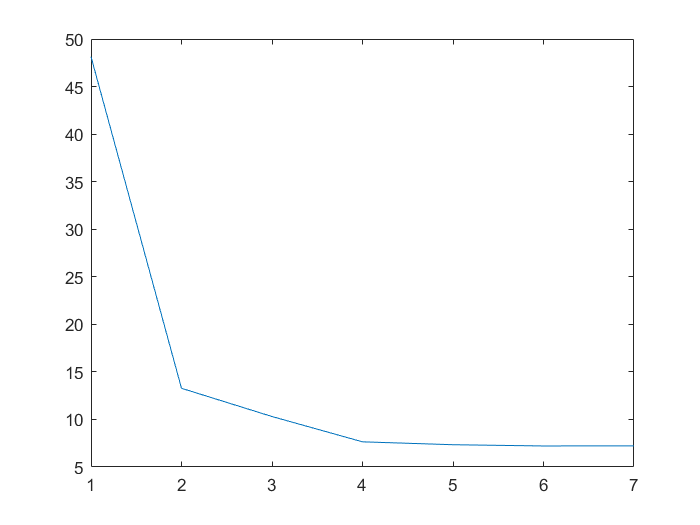

plot(loss_min_chosen);

disp('Note: Here I am using the losses computed from a LOOCV, which could be slightly different from the in-sample errors.')

Note: Here I am using the losses computed from a LOOCV, which could be slightly different from the in-sample errors.


## Nested cross validation with 3 layers

regressors_ind = [1, 2, 3, 4, 5, 6, 7];

num_folds_outer = n;

rem = mod(n, num_folds_outer);
num_observs_each_fold = (n - rem) / num_folds_outer;
num_observs_folds = num_observs_each_fold * ones(num_folds_outer, 1);
for i = 1 : rem
    num_observs_folds(i) = num_observs_folds(i) + 1;
end

X_covariates = data(1 : n, regressors_ind);
Y = data(1 : n, explained_var_ind);
num_covariates_total = size(X_covariates, 2);
L00_MSE_cov_select_models = zeros(num_covariates_total, 1);
l2_outer_testScore = zeros(num_folds_outer, 1);
l2_outer_testScore_norm = zeros(num_folds_outer, 1);
ind_cov_forward_greedy = struct('inds', []);
ind_cov_infold = struct('inds', []);
m = 1;

for i = 1 : num_folds_outer
    
    Y_outer_train_folds = Y([1 : m-1, m + num_observs_folds(i) : end]);
    X_outer_train_folds = X_covariates([1 : m-1, m + num_observs_folds(i) : end], :);
    Y_outer_test = Y(m : m + num_observs_folds(i) - 1);
    X_outer_test = X_covariates(m : m + num_observs_folds(i) - 1, :);
    m = m + num_observs_folds(i);
    length_outer_train = length(Y_outer_train_folds);
    
    indices = (randperm(length_outer_train, floor(0.7*length_outer_train)))';
    length_pseudo_outer_train = length(indices);
    set_ind_all = 1 : length_outer_train;
    rest_ind = setdiff(set_ind_all, indices);
    
    Y_pseudo_outer_train_folds = Y_outer_train_folds(indices);
    X_pseudo_outer_train_folds = X_outer_train_folds(indices, :);
    
    length_pseudo_outer_test = length_outer_train - length_pseudo_outer_train;
    Y_pseudo_outer_test_folds = Y_outer_train_folds(rest_ind);
    X_pseudo_outer_test_folds = X_outer_train_folds(rest_ind, :);
    
    set_of_covariates = 1 : num_covariates_total;
    set_of_selected_covariates = [];
    l2_pseudo_outer_test_score = zeros(num_covariates_total, 1);
    k = 1;
    while ~isempty(set_of_covariates)
        
        indnum = 0;
        L00_cov_select_cur = zeros(length(set_of_covariates), num_observs_folds(i));
        for l = set_of_covariates
            
            indnum = indnum + 1;
            selModelInd = [set_of_selected_covariates, l];
            
            for j = 1 : length(Y_pseudo_outer_train_folds)
                
                Y_inner_train_folds = Y_pseudo_outer_train_folds([1 : j - 1, j + 1 : end]);
                X_inner_train_folds = X_pseudo_outer_train_folds([1 : j - 1, j + 1 : end], :);
                
                Y_inner_test = Y_pseudo_outer_train_folds(j);
                X_inner_test = X_pseudo_outer_train_folds(j, :);
                
                X_inner_train_folds_in = X_inner_train_folds(:, selModelInd);
                X_inner_test_folds_in = X_inner_test(:, selModelInd);
                
                [X_inner_train_folds_in_norm, mu_x_fold, sigma_x_fold] = featureNormalize(X_inner_train_folds_in);
                [X_inner_test_in_norm] = featureNormalize2(X_inner_test_folds_in, mu_x_fold, sigma_x_fold);
                
                [Y_inner_train_folds_norm, my_y_fold, sigma_y_fold] = featureNormalize(Y_inner_train_folds);
                
                beta_OLS = pinv(X_inner_train_folds_in_norm' * X_inner_train_folds_in_norm) * (X_inner_train_folds_in_norm' * Y_inner_train_folds_norm);
                
                Y_inner_test_pred = X_inner_test_in_norm * beta_OLS;
                Y_inner_train_folds_pred = X_inner_train_folds_in_norm * beta_OLS;
                
                Y_train_folds_pred_denorm = featureDenormalize(Y_inner_train_folds_pred, my_y_fold, sigma_y_fold);
                Y_inner_test_pred_denorm = featureDenormalize(Y_inner_test_pred, my_y_fold, sigma_y_fold);
                
                L00_cov_select_cur(indnum, j) = mean((Y_inner_test - Y_inner_test_pred_denorm).^2);
            end
        end
        
        L00_MSE_cov_select = mean(L00_cov_select_cur, 2);
        [L00_MSE_cov_select_models(k), indWinCovariate] = min(L00_MSE_cov_select);
        winCovariate = set_of_covariates(indWinCovariate);
        set_of_selected_covariates = [set_of_selected_covariates, winCovariate];
        set_of_covariates = set_of_covariates(set_of_covariates~=winCovariate);
        
        [Y_inner_train_folds_norm, mu_y_inner, sigma_y_inner] = featureNormalize(Y_pseudo_outer_train_folds);
        [X_inner_train_folds_norm, mu_x_inner, sigma_x_inner] = featureNormalize(X_pseudo_outer_train_folds(:, set_of_selected_covariates));
        [X_inner_test_folds_norm] = featureNormalize2(X_pseudo_outer_test_folds(:, set_of_selected_covariates), mu_x_inner, sigma_x_inner);
        
        beta_OLS = pinv(X_inner_train_folds_norm' * X_inner_train_folds_norm) * (X_inner_train_folds_norm' * Y_inner_train_folds_norm);
        
        Y_inner_pred = X_inner_test_folds_norm * beta_OLS;
        Y_inner_pred_denorm = featureNormalize2(Y_inner_pred, mu_y_inner, sigma_y_inner);
        l2_pseudo_outer_test_score(k) = mean((Y_inner_pred_denorm - Y_pseudo_outer_test_folds).^2);
        
        ind_cov_infold(k).inds = set_of_selected_covariates;
        k = k + 1;
    end
    
    [~, winningModel] = min(l2_pseudo_outer_test_score);
    set_of_winning_covariates = ind_cov_infold(winningModel).inds;
    
    [Y_outer_train_folds_norm, mu_y_outer, sigma_y_outer] = featureNormalize(Y_outer_train_folds);
    [X_outer_train_folds_norm, mu_x_outer, sigma_x_outer] = featureNormalize(X_outer_train_folds(:, set_of_winning_covariates));
    [X_outer_test_norm] = featureNormalize2(X_outer_test(:, set_of_winning_covariates), mu_x_outer, sigma_x_outer);
    [Y_outer_test_norm] = featureNormalize2(Y_outer_test, mu_y_outer, sigma_y_outer);
    
    beta_OLS = pinv(X_outer_train_folds_norm' * X_outer_train_folds_norm) * (X_outer_train_folds_norm' * Y_outer_train_folds_norm);
    
    Y_outer_pred = X_outer_test_norm * beta_OLS;
    Y_outer_pred_denorm = featureDenormalize(Y_outer_pred, mu_y_outer, sigma_y_outer);
    l2_outer_testScore(i) = mean((Y_outer_pred_denorm - Y_outer_test).^2);
    l2_outer_testScore_norm(i) = mean((Y_outer_pred - Y_outer_test_norm).^2);
    ind_cov_forward_greedy(i).inds = set_of_winning_covariates;
    
end

l2_outer_testScore_total = mean(l2_outer_testScore);
l2_outer_testScore_total_norm = mean(l2_outer_testScore_norm);

disp('Nested cross validation')

Nested cross validation


disp(['The winning model with regressor indices: ', num2str(set_of_winning_covariates)]);

The winning model with regressor indices: 3  1  4  6


disp(['The statistical risk estimated from the outer loop is: ', num2str(l2_outer_testScore_total)]);

The statistical risk estimated from the outer loop is: 16.8245


disp('Comment: The best model generally aligns with the absolute values of the Pearson correlation, with predictor 2 as an inception. It could be that it is highly correlated with another predictor.')

Comment: The best model generally aligns with the absolute values of the Pearson correlation, with predictor 2 as an inception. It could be that it is highly correlated with another predictor.


## Regression and evaluation using the final model

regressor_ind = set_of_winning_covariates;
explained_var_ind = 10;

### Normalization

Normalize the training sample: 

[X_norm, mu_x, sigma_x] = featureNormalize(train_sample(:, regressor_ind));

X_train = [ones(train_size, 1), X_norm];
Y_train = train_sample(:, explained_var_ind);

Apply the same transformation on the test sample:

test_sample_temp = test_sample(:, regressor_ind) - mu_x;
test_sample_temp = test_sample_temp ./ sigma_x;
X_test = [ones(test_size, 1), test_sample_temp];
Y_test = test_sample(:, explained_var_ind);

Apply the closed-form normal equation:

beta_OLS_explicit_winning = OLS_normalequation(X_train, Y_train);

Compare with the result from Matlab internal regression function:

[beta_OLS_winning, beta_OLS_confint_winning] = regress(Y_train, X_train);

### Compute training error

Construct the output of the trained (estimated) model or the in-sample values of the explained variable.

Y_hat_train = X_train * beta_OLS_winning;

Loss L1:

loss_l1_winning_train = loss_l1(Y_hat_train, Y_train);
disp('Results for the winning model using fly ash, cement, water and coarse aggregate as regressors: ')

Results for the winning model using fly ash, cement, water and coarse aggregate as regressors: 


disp(['The training error measured by l1 loss is ', num2str(loss_l1_winning_train)]);

The training error measured by l1 loss is 2.02


Loss L2:

loss_l2_winning_train = loss_l2(Y_hat_train, Y_train);
disp(['The training error measured by l2 loss is ', num2str(loss_l2_winning_train)]);

The training error measured by l2 loss is 6.6742


Huber loss:

loss_huber_winning_train = loss_huber(Y_hat_train, Y_train, delta);
disp(['The training error measured by Huber loss is ', num2str(loss_huber_winning_train)]);

The training error measured by Huber loss is 3.3371


### Compute test error

Y_hat_test = X_test * beta_OLS_winning;

Loss L1:

loss_l1_winning_test = loss_l1(Y_hat_test, Y_test);
disp(['The test error measured by l1 loss is ', num2str(loss_l1_winning_test)]);

The test error measured by l1 loss is 2.5408


Loss L2:

loss_l2_winning_test = loss_l2(Y_hat_test, Y_test);
disp(['The training error measured by l2 loss is ', num2str(loss_l2_winning_test)]);

The training error measured by l2 loss is 11.1894


Huber loss:

loss_huber_winning_test = loss_huber(Y_hat_test, Y_test, delta);
disp(['The training error measured by Huber loss is ', num2str(loss_huber_winning_test)]);

The training error measured by Huber loss is 5.5947


disp('The test error is much lower than those in part 1 and 2.')

The test error is much lower than those in part 1 and 2.
